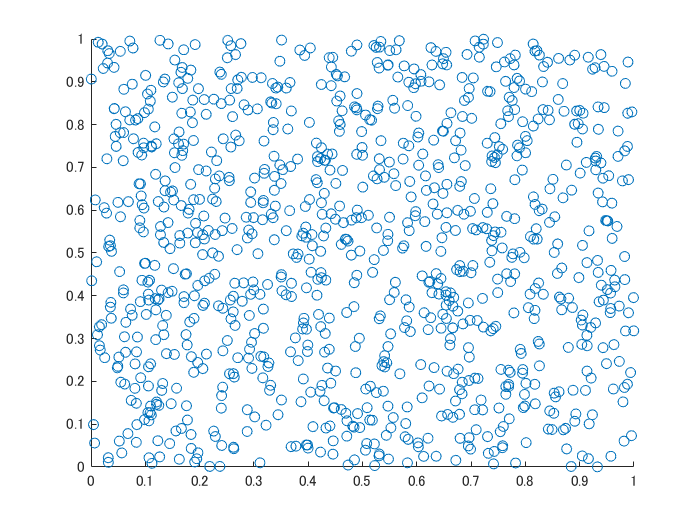

data = rand(1000,2);

figure(1)
x = data(:,1);
y = data(:,2);
scatter(x,y);

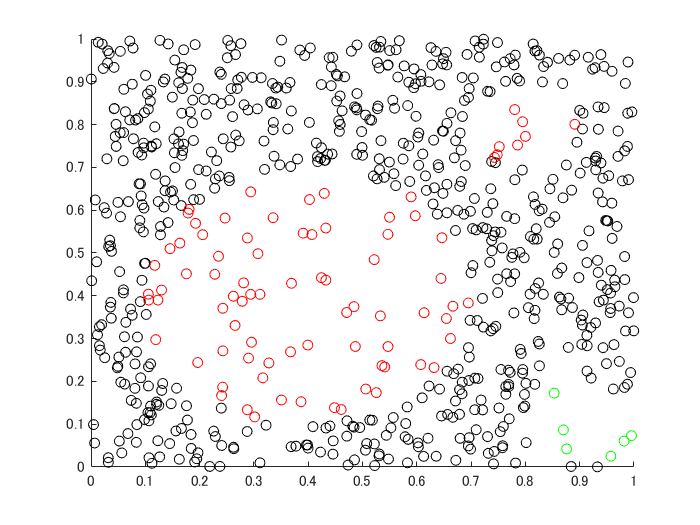


% center = (0.4,0.4), radius = 0.3
idx1a = (x-0.4).^2 + (y-0.4).^2 < 0.3^2;
% center = (0.8,0.8), radius = 0.1
idx1b = (x-0.8).^2 + (y-0.8).^2 < 0.1^2;
% center = (0.9,0.1), radius = 0.1
idx2 = (x-0.9).^2 + (y-0.1).^2 < 0.1^2;

N = 4;
data1 = data(idx1a|idx1b,:);
data1 = data1(1:N:end,:);
data2 = data(idx2,:);
data2 = data2(1:N:end,:);

data(idx1a|idx1b|idx2,:) = [];

figure(2)
scatter(data(:,1),data(:,2),'black');
hold on
scatter(data1(:,1),data1(:,2),'red');
scatter(data2(:,1),data2(:,2),'green');
hold off

label0 = repmat("class0",length(data),1);
label1 = repmat("class1",length(data1),1);
label2 = repmat("class2",length(data2),1);

dataset = array2table([data;data1;data2]);
dataset = addvars(dataset, [label0;label1;label2],...
    'NewVariableNames','label');
labels = dataset(:,end);
t = tabulate(dataset.label)

t = 3×3 の cell 配列
    {'class0'}    {[649]}    {[88.0597]}
    {'class1'}    {[ 82]}    {[11.1262]}
    {'class2'}    {[  6]}    {[ 0.8141]}


uniqueLabels = string(t(:,1));
labelCounts = cell2mat(t(:,2));
% Default
Nmax = max(labelCounts);
% N2generate = Nmax - labelCounts;
N2generate = [0,100,10];

k = 5;
newdata = table;
visdataset = cell(length(uniqueLabels),1);
for ii=1:length(uniqueLabels)
%         [tmp,visdata] = mySMOTE(dataset,uniqueLabels(ii),N2generate(ii),k);
    [tmp,visdata]  = myADASYN(dataset,uniqueLabels(ii),N2generate(ii),k);
%         [tmp,visdata] = myBorderlineSMOTE(dataset,uniqueLabels(ii),N2generate(ii),k);
%         [tmp,visdata] = mySafeLevelSMOTE(dataset,uniqueLabels(ii),N2generate(ii),k);
    newdata = [newdata; tmp];
    visdataset{ii} = visdata;
end

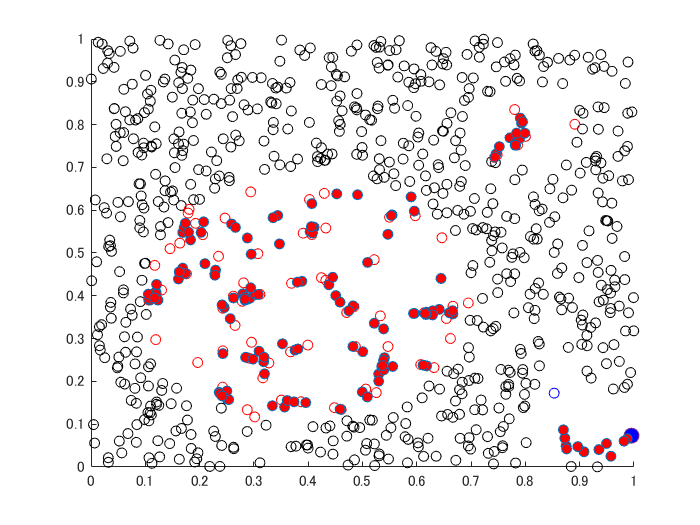


%%
figure(3)
scatter(data(:,1),data(:,2),'black');
hold on
scatter(data1(:,1),data1(:,2),'red');
scatter(data2(:,1),data2(:,2),'green');

hl1 = plot(0,0,'LineStyle','none','Marker','o','MarkerFaceColor','b');
hl2 = plot(0,0,'LineStyle','none','Marker','o','MarkerEdgeColor','b');
hl3 = plot(0,0,'LineStyle','none','Marker','o','MarkerFaceColor','g');
hl4 = plot(0,0,'LineStyle','none','Marker','o','MarkerFaceColor','y');

if exist('hl5',"var")
    clear hl5;
end
for ii=1:length(uniqueLabels)
    visdata = visdataset{ii};
    if length(visdata) == 1
        continue
    end
    for jj=1:length(visdata)
        y = visdata{jj,1};
        yknn = visdata{jj,2};
        y2 = visdata{jj,3};
        newy = visdata{jj,4};
        
        hl1.XData = y(1);
        hl1.YData = y(2);
        hl1.MarkerSize = 9;
        hl2.XData = yknn(:,1);
        hl2.YData = yknn(:,2);
        hl3.XData = y2(1);
        hl3.YData = y2(2);
        pause(0.1)
        hl4.XData = newy(1);
        hl4.YData = newy(2);
        
        if exist('hl5',"var")
            hl5.XData = [hl5.XData,newy(1)];
            hl5.YData = [hl5.YData,newy(2)];
        else
            hl5 = plot(newy(1),newy(2),'LineStyle','none',...
                'Marker','o','MarkerFaceColor','r');
        end
        drawnow
        pause(0.3)
    end
end


hold off